rawDataPath_cells_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003425/Record/000002/data.raw.h5';
rawDataPath_cells_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000006/data.raw.h5';
rawDataPath_cells_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003425/Record/000018/data.raw.h5';

rawDataPath_media_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003486/Record/000001/data.raw.h5';rawDataPath_media_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000006/data.raw.h5';
rawDataPath_media_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000008/data.raw.h5';
rawDataPath_media_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003486/Record/000020/data.raw.h5';

rawpath = '/recordings/rec0000/well000/groups/routed';
wellID = 1;

cellsRawDataMedia = mxw.fileManager(rawDataPath_cells_media,wellID);
cellsRawDataT0 = mxw.fileManager(rawDataPath_cells_T0,wellID);
cellsRawDataD1 = mxw.fileManager(rawDataPath_cells_D1,wellID);

mediaRawDataMedia = mxw.fileManager(rawDataPath_media_media,wellID);
mediaRawDataT0 = mxw.fileManager(rawDataPath_media_T0,wellID);
mediaRawDataD1 = mxw.fileManager(rawDataPath_media_D1,wellID);


samplingFrequency = 20000;
highPassCutOff = 0.1;
bandwidth = [200 3500];
numSeconds = 20;


cellsTableT0 = createRecordingTable(cellsRawDataT0,numSeconds,1,1);
cellsTableT0 = highPassFilterTraces(cellsTableT0,highPassCutOff,samplingFrequency);
[cellsTableT0, ctrlAvPSD, ctrlAvfreq] = calculatePSDs(cellsTableT0,samplingFrequency);

[ctrlAvRMS] = calculateAverageRMS(ctrlAvPSD,ctrlAvfreq,bandwidth);
disp(ctrlAvRMS);

   3.7753e-06




cellsTableT0 = calculateRMSs(cellsTableT0, bandwidth);
cellsTableT0 = calculateResistances(cellsTableT0, bandwidth);

nRecordings = 1;
controlTable = cellsTableT0;

cellsTableArray = cell(1,nRecordings);
cellsAvRMSArray = zeros(1,nRecordings);
cellsAvPSDArray = cell(1,nRecordings);
cellsAvDiffPSDArray = cell(1,nRecordings);
cellsAvFreqArray = cell(1,nRecordings);


for i = 1:1:nRecordings

    cellsTableArray{i} = createRecordingTable(cellsRawDataD1,numSeconds,1,i);
    cellsTableArray{i} = highPassFilterTraces(cellsTableArray{i},highPassCutOff,samplingFrequency);

    [cellsTableArray{i},cellsAvPSDArray{i},cellsAvFreqArray{i}] = calculatePSDs(cellsTableArray{i},samplingFrequency);
    [cellsAvRMSArray(i)] = calculateAverageRMS(cellsAvPSDArray{i},cellsAvFreqArray{i},bandwidth);

    [cellsTableArray{i},cellsAvDiffPSDArray{i}] = calculateDifferentialPSDs(cellsTableArray{i},controlTable);

    cellsTableArray{i} = calculateDifferentialRMSs(cellsTableArray{i}, bandwidth);
    cellsTableArray{i} = calculateDifferentialResistances(cellsTableArray{i}, bandwidth);
    
    disp(cellsAvRMSArray(i))
end

   3.9216e-06




cellsAvPSDArray = cell2mat(cellsAvPSDArray);
cellsAvDiffPSDArray = cell2mat(cellsAvDiffPSDArray);
cellsAvFreqArray = cell2mat(cellsAvFreqArray);


clf('reset');

loglog(ctrlAvfreq,sqrt(ctrlAvPSD));

hold on;
loglog(cellsAvFreqArray,sqrt(cellsAvPSDArray));
hold off;

colorMapLength = nRecordings + 1;
red = [1,0,0];
blue = [0,0,1];
black = [0,0,0];


colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
colours_ctrl = black;
ax=gca;
ax.ColorOrder = cat(1,colours_ctrl,colours_scale);


legend('MDA-MB-231 Cells at Hour 1' ...
    ,'', '','','','','','','','','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','','','','','MDA-MB-231 Cells at Hour 45','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','', ...
    'MDA-MB-231 Cells at Hour 70','Media Control')

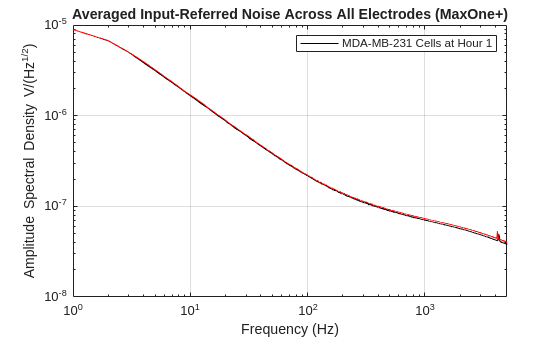


xlim([0 5000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})')
title('Averaged Input-Referred Noise Across All Electrodes (MaxOne+)')
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')

clf('reset');



loglog(cellsAvFreqArray,cellsAvDiffPSDArray());


colorMapLength = nRecordings + 1;
red = [1,0,0];
blue = [0,0,1];
black = [0,0,0];


colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
colours_ctrl = black;
ax=gca;
ax.ColorOrder = cat(1,colours_ctrl,colours_scale);


legend('MDA-MB-231 Cells at Hour 1' ...
    ,'', '','','','','','','','','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','','','','','MDA-MB-231 Cells at Hour 45','' ...
    ,'','','','','','','','','','' ...
    ,'','','','','', ...
    'MDA-MB-231 Cells at Hour 70','Media Control')

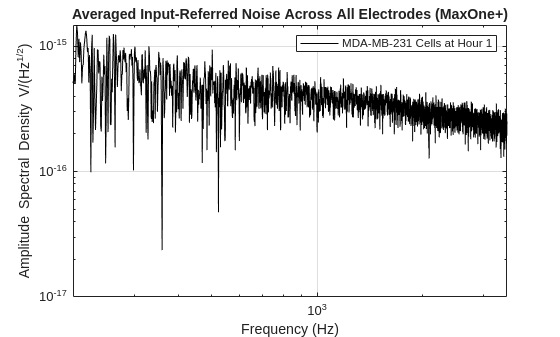


xlim([bandwidth(1) bandwidth(2)]);
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})')
title('Averaged Input-Referred Noise Across All Electrodes (MaxOne+)')
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')

cellsFullTableT0 = createFullElectrodeTable(cellsRawDataT0);
cellsFullTableT0 = addSurfaceScanData(cellsFullTableT0,surfaceScanCellsT0);

cellsFullTableD1 = createFullElectrodeTable(cellsRawDataD1);
cellsFullTableD1 = addSurfaceScanData(cellsFullTableD1,surfaceScanCellsD1);
cellsFullTableD1 = calculateDifferentialSurfaceScanData(cellsFullTableD1,surfaceScanCellsT0);

disp(cellsFullTableD1);

    electrodeNums      xs        ys      surfaceScanVals    diffSurfaceScanVals
    _____________    ______    ______    _______________    ___________________

            0             0         0        85.396                 0.084      
            1          17.5         0        84.101                0.0754      
            2            35         0         83.85                0.0575      
            3          52.5         0        84.329                0.1287      
            4            70         0        85.486                0.0961      
            5          87.5         0        83.864                0.1199      
            6           105         0        80.189                0.2257      
            7         122.5         0        85.466                0.1439      
            8           140  

disp(cellsTableArray{1});

    electrodeNums      xs        ys         rawTraces       filteredTraces          PSDs          frequencies         diffPSDs              diffRMSs           diffVariances    diffResistances
    _____________    ______    ______    _______________    _______________    ______________    ______________    ______________    ______________________    _____________    _______________

            0             0         0    1×400000 double    1×400000 double    1×10001 double    1×10001 double    1×10001 double     5.043e-06+0i               2.5432e-11        4.5037e+05  
            5          87.5         0    1×400000

memberElectrodesBool = ismember(cellsFullTableD1.electrodeNums,cellsTableArray{1}.electrodeNums);
mappedElectrodesDiffResistances = zeros(length(cellsFullTableD1.electrodeNums),1)

mappedElectrodesDiffResistances =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


index = 1;
for i = 1:length(cellsFullTableD1.electrodeNums)
    if memberElectrodesBool(i) == 1
           mappedElectrodesDiffResistances(i) = cellsTableArray{1}.diffResistances(index);

            index=index+1;
    end
end
mappedDiffResistances = (mappedElectrodesDiffResistances);
cellsFullTableD1 = addvars(cellsFullTableD1,mappedDiffResistances);

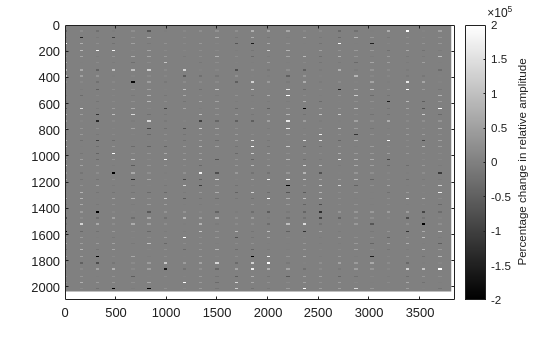

Z = reshape(transpose(cellsFullTableD1.mappedDiffResistances),220,120);
h1 = imagesc(cellsTableArray{1}.xs,cellsTableArray{1}.ys,Z);
colormap(gca,"gray");

clim([-200E3,200E3])
cb = colorbar;
cb.Label.String = "Percentage change in relative amplitude";
ax = gca;
ylim([0 2100]);
xlim([0 3850]);

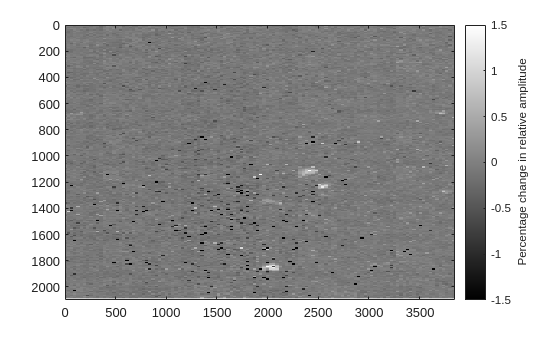

Z = reshape(transpose(cellsFullTableD1.diffSurfaceScanVals),220,120);
h1 = imagesc(cellsFullTableD1.xs,cellsFullTableD1.ys,-Z);
colormap(gca,"gray");

clim([-1.5,1.5])
cb = colorbar;
cb.Label.String = "Percentage change in relative amplitude";
ax = gca;
ylim([0 2100]);
xlim([0 3850]);

nonZeroRes = cellsFullTableD1.mappedDiffResistances(cellsFullTableD1.mappedDiffResistances ~= 0)

nonZeroRes = 1.0e+05 *

    4.5037
   -0.3897
   -0.1152
    2.6723
   -0.1064
    0.2355
    0.6963
    0.8667
    1.0755
    0.2610
    0.0960
   -0.1263
   -0.1252
   -0.5180
    0.8208


nonZeroScan = cellsFullTableD1.diffSurfaceScanVals(cellsFullTableD1.mappedDiffResistances ~= 0)

nonZeroScan =     0.0840
    0.1199
    0.0503
    0.1559
    0.1312
    0.1826
    0.0524
    0.0377
    0.0859
    0.0856
    0.1378
   -0.0065
    0.1447
    0.2352
   -0.0754


corr(nonZeroRes,nonZeroScan,'Type','Spearman')

ans = 0.0078


mediaTableT0 = createRecordingTable(mediaRawDataT0,numSeconds,1,1);
mediaTableT0 = highPassFilterTraces(mediaTableT0,highPassCutOff,samplingFrequency);
[mediaTableT0, ctrlAvPSD, ctrlAvfreq] = calculatePSDs(mediaTableT0,samplingFrequency);

[ctrlAvRMS] = calculateAverageRMS(ctrlAvPSD,ctrlAvfreq,bandwidth);
disp(ctrlAvRMS);

   3.4690e-06




mediaTableT0 = calculateRMSs(mediaTableT0, bandwidth);
mediaTableT0 = calculateResistances(mediaTableT0, bandwidth);

nRecordings = 1;
controlTable = mediaTableT0;

mediaTableArray = cell(1,nRecordings);
mediaAvRMSArray = zeros(1,nRecordings);
mediaAvPSDArray = cell(1,nRecordings);
mediaAvDiffPSDArray = cell(1,nRecordings);
mediaAvFreqArray = cell(1,nRecordings);


for i = 1:1:nRecordings

    mediaTableArray{i} = createRecordingTable(mediaRawDataD1,numSeconds,1,i);
    mediaTableArray{i} = highPassFilterTraces(mediaTableArray{i},highPassCutOff,samplingFrequency);

    [mediaTableArray{i},mediaAvPSDArray{i},mediaAvFreqArray{i}] = calculatePSDs(mediaTableArray{i},samplingFrequency);
    [mediaAvRMSArray(i)] = calculateAverageRMS(mediaAvPSDArray{i},mediaAvFreqArray{i},bandwidth);

    [mediaTableArray{i},mediaAvDiffPSDArray{i}] = calculateDifferentialPSDs(mediaTableArray{i},controlTable);

    mediaTableArray{i} = calculateDifferentialRMSs(mediaTableArray{i}, bandwidth);
    mediaTableArray{i} = calculateDifferentialResistances(mediaTableArray{i}, bandwidth);
    
    disp(mediaAvRMSArray(i))
end

   3.4287e-06




mediaAvPSDArray = cell2mat(mediaAvPSDArray);
mediaAvDiffPSDArray = cell2mat(mediaAvDiffPSDArray);
mediaAvFreqArray = cell2mat(mediaAvFreqArray);


mediaFullTableT0 = createFullElectrodeTable(mediaRawDataT0);
mediaFullTableT0 = addSurfaceScanData(mediaFullTableT0,surfaceScanMediaT0);

mediaFullTableD1 = createFullElectrodeTable(mediaRawDataD1);
mediaFullTableD1 = addSurfaceScanData(mediaFullTableD1,surfaceScanMediaD1);
mediaFullTableD1 = calculateDifferentialSurfaceScanData(mediaFullTableD1,surfaceScanMediaT0);


memberElectrodesBool = ismember(mediaFullTableD1.electrodeNums,mediaTableArray{1}.electrodeNums);
mappedElectrodesDiffResistances = zeros(length(mediaFullTableD1.electrodeNums),1)

mappedElectrodesDiffResistances =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


index = 1;
for i = 1:length(mediaFullTableD1.electrodeNums)
    if memberElectrodesBool(i) == 1
           mappedElectrodesDiffResistances(i) = mediaTableArray{1}.diffResistances(index);

            index=index+1;
    end
end
mappedDiffResistances = (mappedElectrodesDiffResistances);
mediaFullTableD1 = addvars(mediaFullTableD1,mappedDiffResistances);

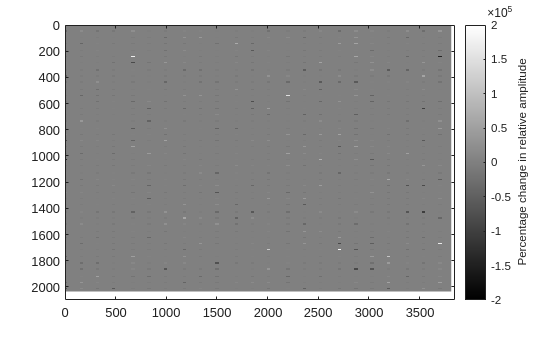

Z = reshape(transpose(mediaFullTableD1.mappedDiffResistances),220,120);
h1 = imagesc(mediaTableArray{1}.xs,mediaTableArray{1}.ys,Z);
colormap(gca,"gray");

clim([-200E3,200E3])
cb = colorbar;
cb.Label.String = "Percentage change in relative amplitude";
ax = gca;
ylim([0 2100]);
xlim([0 3850]);

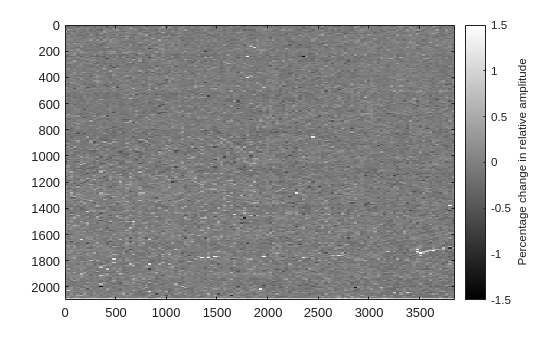

Z = reshape(transpose(mediaFullTableD1.diffSurfaceScanVals),220,120);
h1 = imagesc(mediaFullTableD1.xs,mediaFullTableD1.ys,-Z);
colormap(gca,"gray");

clim([-1.5,1.5])
cb = colorbar;
cb.Label.String = "Percentage change in relative amplitude";
ax = gca;
ylim([0 2100]);
xlim([0 3850]);

function T = createRecordingTable(rawData,numSeconds,correctionFactor,recordingNum)
        
        startSample = 1;
        subset = [1 rawData.fileObj(1).nChannels];
        %subset = [400 500];
        

        electrodeNums = rawData.rawMap(1).map.electrode(subset(1):subset(2));
        xs = rawData.rawMap(1).map.x(subset(1):subset(2));
        ys = rawData.rawMap(1).map.y(subset(1):subset(2));
        rawTraces = rawData.extractRawData(startSample,numSeconds*rawData.fileObj(1).samplingFreq,'file',recordingNum);
         
        rawTraces = transpose(rawTraces(:,subset(1):subset(2)));
        rawTraces = (rawTraces./(1E6))*correctionFactor;

        T = table(electrodeNums,xs,ys,rawTraces);
        T = sortrows(T);
end

function T = createFullElectrodeTable(rawData)
        
           recordingElectrodes = rawData.processedMap.electrode();
           unroutedElectrodes = rawData.processedMap.nonRoutedElec();

           electrodeNums = cat(1,recordingElectrodes,unroutedElectrodes);
           electrodeNums = sort(electrodeNums);
           len = length(electrodeNums);

           xs = zeros(1,len);
           ys = zeros(1,len);

           for i = 1:len
                ys(i) = ceil(i/220) ;
                xs(i) = i - (220*(ys(i)-1));

           end

           xs = xs-1;
           ys = ys-1;

           xs = transpose(xs*17.5);
           ys = transpose(ys*17.5);
           
           T = table(electrodeNums,xs,ys);
 
end

function T = addSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    T = addvars(T,scanT.Var2,'NewVariableNames','surfaceScanVals');

end

function T = calculateDifferentialSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    diffVals = T.surfaceScanVals - scanT.Var2;

    T = addvars(T,diffVals,'NewVariableNames','diffSurfaceScanVals');

end

    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq)
    
        resolution = 1;
        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        avPSD = sum(PSDs,2)/size(PSDs,2);
        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/size(differentialPSDs,2);

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth)

        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end

function T = calculateRMSs(T,bandwidth)

        len = height(T);
        RMSs = zeros(len, 1);
        variances = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
            variances(i) = trapz(f,PSD); 
        end

        T = addvars(T, RMSs,variances,'NewVariableNames',{'RMSs','variances'});

end

function T = calculateDifferentialRMSs(T,bandwidth)

        len = height(T);
        diffVariances = zeros(len, 1);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
            diffVariances(i) = trapz(f,diffPSD); 
        end

        T = addvars(T, diffRMSs,diffVariances, 'NewVariableNames',{'diffRMSs','diffVariances'});

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.variances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
         
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffVariances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end

